clear;
clc;

set( groot, 'defaultLineLineWidth', 1.2 ) ; % plot line 두께 지정
set( groot, 'defaultAxesXGrid', 'on' ) ; % x축 방향으로 grid 생성
set( groot, 'defaultAxesYGrid', 'on' ) ; % y축 방향으로 grid 생성
set( groot, 'defaultAxesTitleFontSizeMultiplier', 1.5);  % Title 크기 설정
set( groot, 'defaultAxesFontSize', 12 ); % 축에 있는 글씨 크기 지정
set( groot, 'defaultAxesFontName', 'Times New Roman'); % 축에 있는 글씨 폰트 지정
set( groot, 'defaultFigureColor', 'w'); % figure 색상

% Load data
dateStr = '20250701';      % log date
runIdx  = 'wo_distribution_update';             % log nums

scriptFullPath = matlab.desktop.editor.getActiveFilename;
currentDir = fileparts(scriptFullPath);

while true
    [parentDir, folderName] = fileparts(currentDir);
    if strcmp(folderName, 'mppi_solver')
        projectRoot = currentDir;
        break;
    end
    if isempty(parentDir)
        error('Directory mppi_solver not found');
    end
    currentDir = parentDir;
end

absPath = fullfile(projectRoot, 'runs', ...
                   dateStr, runIdx, 'mppi_canadarm');

wo_ee_pose = h5read(fullfile(absPath, 'end_effector_pose.mat'), '/end_effector_pose');
wo_pos_err = h5read(fullfile(absPath, 'end_effector_pose.mat'), '/pos_err');
wo_ori_err = h5read(fullfile(absPath, 'end_effector_pose.mat'), '/ori_err');
wo_cost    = h5read(fullfile(absPath, 'end_effector_pose.mat'), '/cost');
wo_sigma   = h5read(fullfile(absPath, 'end_effector_pose.mat'), '/sigma');

clearvars dateStr runIdx scriptFullPath currentDir parentDir folderName projectRoot absPath


% Load data
dateStr = '20250701';      % log date
runIdx  = 'w_distribution_update';             % log nums

scriptFullPath = matlab.desktop.editor.getActiveFilename;
currentDir = fileparts(scriptFullPath);

while true
    [parentDir, folderName] = fileparts(currentDir);
    if strcmp(folderName, 'mppi_solver')
        projectRoot = currentDir;
        break;
    end
    if isempty(parentDir)
        error('Directory mppi_solver not found');
    end
    currentDir = parentDir;
end

absPath = fullfile(projectRoot, 'runs', ...
                   dateStr, runIdx, 'mppi_canadarm');

w_ee_pose = h5read(fullfile(absPath, 'end_effector_pose.mat'), '/end_effector_pose');
w_pos_err = h5read(fullfile(absPath, 'end_effector_pose.mat'), '/pos_err');
w_ori_err = h5read(fullfile(absPath, 'end_effector_pose.mat'), '/ori_err');
w_cost    = h5read(fullfile(absPath, 'end_effector_pose.mat'), '/cost');
w_sigma   = h5read(fullfile(absPath, 'end_effector_pose.mat'), '/sigma');

clearvars dateStr runIdx scriptFullPath currentDir parentDir folderName projectRoot absPath

wo_data_size = size(wo_cost, 2);
w_data_size = size(w_cost, 2);

init_data_idx = 1;
cut_data_idx = min([wo_data_size, w_data_size]);
% without distribution update
wo_ee_pose = wo_ee_pose(:,init_data_idx:cut_data_idx);
wo_pos_err = wo_pos_err(:,init_data_idx:cut_data_idx);
wo_ori_err = wo_ori_err(:,init_data_idx:cut_data_idx);
wo_cost    = wo_cost(:,init_data_idx:cut_data_idx);
wo_sigma   = wo_sigma(:,init_data_idx:cut_data_idx);

wo_ee_pose(1,:) = wo_ee_pose(1,:) - wo_ee_pose(1,1);
wo_pos_err(1,:) = wo_pos_err(1,:) - wo_pos_err(1,1);
wo_ori_err(1,:) = wo_ori_err(1,:) - wo_ori_err(1,1);
wo_cost(1,:)    = wo_cost(1,:)    - wo_cost(1,1);
wo_sigma(1,:)   = wo_sigma(1,:)   - wo_sigma(1,1);

% with distribution update
w_ee_pose = w_ee_pose(:,init_data_idx:cut_data_idx);
w_pos_err = w_pos_err(:,init_data_idx:cut_data_idx);
w_ori_err = w_ori_err(:,init_data_idx:cut_data_idx);
w_cost    = w_cost(:,init_data_idx:cut_data_idx);
w_sigma   = w_sigma(:,init_data_idx:cut_data_idx);

w_ee_pose(1,:) = w_ee_pose(1,:) - w_ee_pose(1,1);
w_pos_err(1,:) = w_pos_err(1,:) - w_pos_err(1,1);
w_ori_err(1,:) = w_ori_err(1,:) - w_ori_err(1,1);
w_cost(1,:)    = w_cost(1,:)    - w_cost(1,1);
w_sigma(1,:)   = w_sigma(1,:)   - w_sigma(1,1);

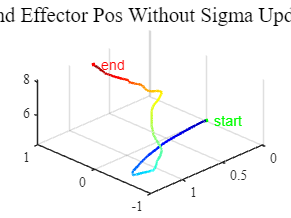

wo_sim_time_ee_pose = wo_ee_pose(1,:);
wo_ee_pos = wo_ee_pose(2:4,:);
wo_ee_ori = wo_ee_pose(5:7,:);

wo_ee_pos_size = size(wo_ee_pos, 2);

figure;
hold on;
colormap(jet(wo_ee_pos_size-1));
cmap = jet(wo_ee_pos_size-1);

for k = 1:wo_ee_pos_size-1
    plot3( ...
      wo_ee_pos(1,k:k+1), wo_ee_pos(2,k:k+1), wo_ee_pos(3,k:k+1), ...
      'Color', cmap(k,:), ...
      'LineWidth', 2 );
end

plot3(wo_ee_pos(1,1), wo_ee_pos(2,1), wo_ee_pos(3,1), 'go', 'MarkerFaceColor','g', 'MarkerSize',2);
text(wo_ee_pos(1,1), wo_ee_pos(2,1), wo_ee_pos(3,1), '  start', 'FontSize',12, 'Color','g');

plot3(wo_ee_pos(1,end), wo_ee_pos(2,end), wo_ee_pos(3,end), 'ro', 'MarkerFaceColor','r', 'MarkerSize',2);
text(wo_ee_pos(1,end), wo_ee_pos(2,end), wo_ee_pos(3,end), '  end', 'FontSize',12, 'Color','r');
hold off;
title("End Effector Pos Without Sigma Update")
view([-1 1 1.5]);

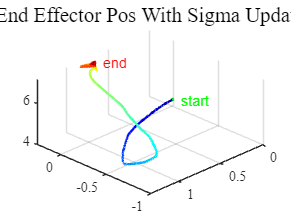



w_sim_time_ee_pose = w_ee_pose(1,:);
w_ee_pos = w_ee_pose(2:4,:);
w_ee_ori = w_ee_pose(5:7,:);

w_ee_pos_size = size(w_ee_pos, 2);

figure;
hold on;
colormap(jet(w_ee_pos_size-1));
cmap = jet(w_ee_pos_size-1);

for k = 1:w_ee_pos_size-1
    plot3( ...
      w_ee_pos(1,k:k+1), w_ee_pos(2,k:k+1), w_ee_pos(3,k:k+1), ...
      'Color', cmap(k,:), ...
      'LineWidth', 2 );
end

plot3(w_ee_pos(1,1), w_ee_pos(2,1), w_ee_pos(3,1), 'go', 'MarkerFaceColor','g', 'MarkerSize',2);
text(w_ee_pos(1,1), w_ee_pos(2,1), w_ee_pos(3,1), '  start', 'FontSize',12, 'Color','g');

plot3(w_ee_pos(1,end), w_ee_pos(2,end), w_ee_pos(3,end), 'ro', 'MarkerFaceColor','r', 'MarkerSize',2);
text(w_ee_pos(1,end), w_ee_pos(2,end), w_ee_pos(3,end), '  end', 'FontSize',12, 'Color','r');
hold off;
title("End Effector Pos With Sigma Update")
view([-1 1 1.5]);

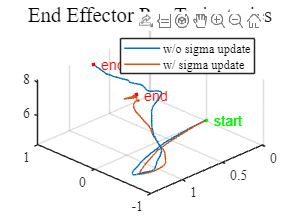



figure;
hold on;
colormap(jet(w_ee_pos_size-1));
cmap = jet(w_ee_pos_size-1);

plot3(wo_ee_pos(1,:), wo_ee_pos(2,:), wo_ee_pos(3,:))
plot3(w_ee_pos(1,:), w_ee_pos(2,:), w_ee_pos(3,:))

plot3(wo_ee_pos(1,1), wo_ee_pos(2,1), wo_ee_pos(3,1), 'go', 'MarkerFaceColor','g', 'MarkerSize',2);
text(wo_ee_pos(1,1), wo_ee_pos(2,1), wo_ee_pos(3,1), '  start', 'FontSize',12, 'Color','g');

plot3(wo_ee_pos(1,end), wo_ee_pos(2,end), wo_ee_pos(3,end), 'ro', 'MarkerFaceColor','r', 'MarkerSize',2);
text(wo_ee_pos(1,end), wo_ee_pos(2,end), wo_ee_pos(3,end), '  end', 'FontSize',12, 'Color','r');

plot3(w_ee_pos(1,1), w_ee_pos(2,1), w_ee_pos(3,1), 'go', 'MarkerFaceColor','g', 'MarkerSize',2);
text(w_ee_pos(1,1), w_ee_pos(2,1), w_ee_pos(3,1), '  start', 'FontSize',12, 'Color','g');

plot3(w_ee_pos(1,end), w_ee_pos(2,end), w_ee_pos(3,end), 'ro', 'MarkerFaceColor','r', 'MarkerSize',2);
text(w_ee_pos(1,end), w_ee_pos(2,end), w_ee_pos(3,end), '  end', 'FontSize',12, 'Color','r');
hold off;
title("End Effector Pos Trajectories")
legend('w/o sigma update', 'w/ sigma update')
view([-1 1 1.5]);

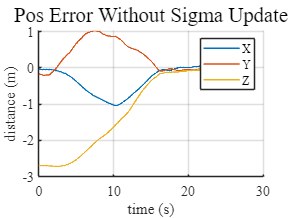

wo_sim_time_pos_err = wo_pos_err(1,:);

figure;
hold on
plot(wo_sim_time_pos_err, wo_pos_err(2,:));
plot(wo_sim_time_pos_err, wo_pos_err(3,:));
plot(wo_sim_time_pos_err, wo_pos_err(4,:));
hold off
title("Pos Error Without Sigma Update")
xlabel("time (s)")
ylabel("distance (m)")
legend("X","Y","Z")

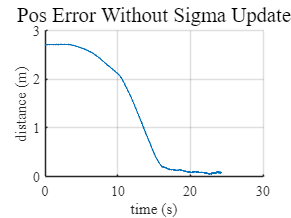


wo_err_dist = vecnorm(wo_pos_err(2:4,:));

figure;
hold on
plot(wo_sim_time_pos_err, wo_err_dist);
hold off
title("Pos Error Without Sigma Update")
xlabel("time (s)")
ylabel("distance (m)")

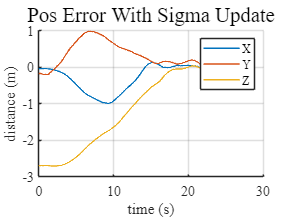



w_sim_time_pos_err = w_pos_err(1,:);

figure;
hold on
plot(w_sim_time_pos_err, w_pos_err(2,:));
plot(w_sim_time_pos_err, w_pos_err(3,:));
plot(w_sim_time_pos_err, w_pos_err(4,:));
hold off
title("Pos Error With Sigma Update")
xlabel("time (s)")
ylabel("distance (m)")
legend("X","Y","Z")

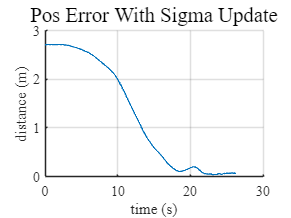


w_err_dist = vecnorm(w_pos_err(2:4,:));

figure;
hold on
plot(w_sim_time_pos_err, w_err_dist);
hold off
title("Pos Error With Sigma Update")
xlabel("time (s)")
ylabel("distance (m)")

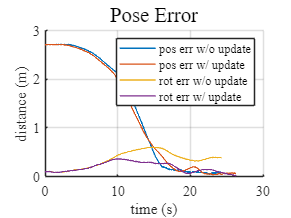



wo_ori_err_dist = vecnorm(wo_ori_err(2:4,:));
w_ori_err_dist = vecnorm(w_ori_err(2:4,:));


% comparision
figure;
hold on
plot(wo_sim_time_pos_err, wo_err_dist);
plot(w_sim_time_pos_err, w_err_dist);
plot(wo_sim_time_pos_err, wo_ori_err_dist);
plot(w_sim_time_pos_err, w_ori_err_dist);
hold off
title("Pose Error")
xlabel("time (s)")
ylabel("distance (m)")
legend('pos err w/o update', 'pos err w/ update', 'rot err w/o update', 'rot err w/ update')

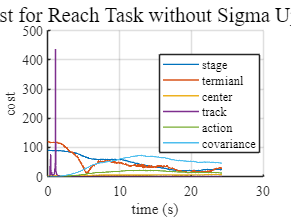

% Without Sigma Update
wo_sim_time_cost   = wo_cost(1,:);
wo_stage_cost      = wo_cost(2,:);
wo_terminal_cost   = wo_cost(3,:);
wo_centering_cost  = wo_cost(4,:);
wo_tracking_cost   = wo_cost(5,:);
wo_action_cost     = wo_cost(6,:);
wo_covar_cost      = wo_cost(7,:);

figure;
hold on
plot(wo_sim_time_cost, wo_stage_cost);
plot(wo_sim_time_cost, wo_terminal_cost);
plot(wo_sim_time_cost, wo_centering_cost);
plot(wo_sim_time_cost, wo_tracking_cost);
plot(wo_sim_time_cost, wo_action_cost);
plot(wo_sim_time_cost, wo_covar_cost);
hold off
title("Cost for Reach Task without Sigma Update")
xlabel("time (s)")
ylabel("cost")
legend("stage", "termianl", "center", "track", "action", "covariance", "Location","best")

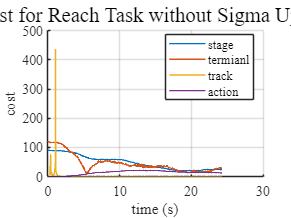


figure;
hold on
plot(wo_sim_time_cost, wo_stage_cost);
plot(wo_sim_time_cost, wo_terminal_cost);
plot(wo_sim_time_cost, wo_tracking_cost);
plot(wo_sim_time_cost, wo_action_cost);
hold off
title("Cost for Reach Task without Sigma Update")
xlabel("time (s)")
ylabel("cost")
legend("stage", "termianl", "track", "action", "Location","best")

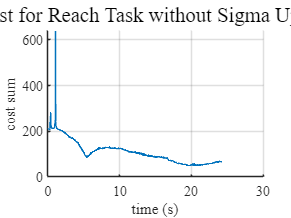


% wo_reach_cost = wo_stage_cost + wo_terminal_cost + wo_centering_cost +...
%                 wo_tracking_cost + wo_action_cost + wo_covar_cost;

wo_reach_cost = wo_stage_cost + wo_terminal_cost + wo_tracking_cost + wo_action_cost;

figure;
hold on
plot(wo_sim_time_cost, wo_reach_cost);
hold off
title("Cost for Reach Task without Sigma Update")
xlabel("time (s)")
ylabel("cost sum")

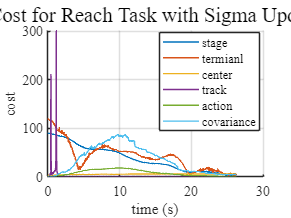


% With Sigma Update

w_sim_time_cost   = w_cost(1,:);
w_stage_cost      = w_cost(2,:);
w_terminal_cost   = w_cost(3,:);
w_centering_cost  = w_cost(4,:);
w_tracking_cost   = w_cost(5,:);
w_action_cost     = w_cost(6,:);
w_covar_cost      = w_cost(7,:);

figure;
hold on
plot(w_sim_time_cost, w_stage_cost);
plot(w_sim_time_cost, w_terminal_cost);
plot(w_sim_time_cost, w_centering_cost);
plot(w_sim_time_cost, w_tracking_cost);
plot(w_sim_time_cost, w_action_cost);
plot(w_sim_time_cost, w_covar_cost);
hold off
title("Cost for Reach Task with Sigma Update")
xlabel("time (s)")
ylabel("cost")
legend("stage", "termianl", "center", "track", "action", "covariance", "Location","best")

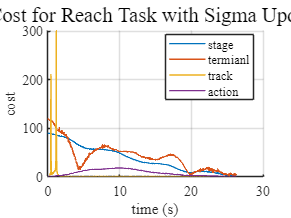


figure;
hold on
plot(w_sim_time_cost, w_stage_cost);
plot(w_sim_time_cost, w_terminal_cost);
plot(w_sim_time_cost, w_tracking_cost);
plot(w_sim_time_cost, w_action_cost);
hold off
title("Cost for Reach Task with Sigma Update")
xlabel("time (s)")
ylabel("cost")
legend("stage", "termianl", "track", "action", "Location","best")

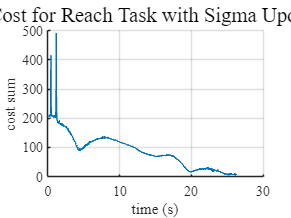


% w_reach_cost = w_stage_cost + w_terminal_cost + w_centering_cost +...
%                 w_tracking_cost + w_action_cost + w_covar_cost;

w_reach_cost = w_stage_cost + w_terminal_cost + w_tracking_cost + w_action_cost;

figure;
hold on
plot(w_sim_time_cost, w_reach_cost);
hold off
title("Cost for Reach Task with Sigma Update")
xlabel("time (s)")
ylabel("cost sum")

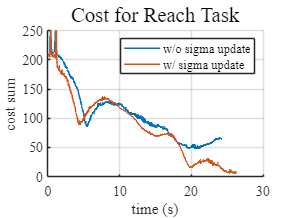



% comparision
figure;
hold on
plot(wo_sim_time_cost, wo_reach_cost);
plot(w_sim_time_cost, w_reach_cost);
hold off
title("Cost for Reach Task")
xlabel("time (s)")
ylabel("cost sum")
legend('w/o sigma update', 'w/ sigma update')
ylim([0 250])

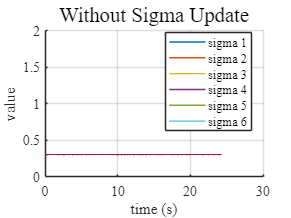

wo_sim_time_sigma = wo_sigma(1,:);
wo_sigma_value    = wo_sigma(2:end,:);

figure;
hold on
plot(wo_sim_time_sigma, wo_sigma_value);
hold off
title("Without Sigma Update")
xlabel("time (s)")
ylabel("value")
ylim([0 2])
legend("sigma 1", "sigma 2", "sigma 3", "sigma 4", "sigma 5", "sigma 6", "Location","best")

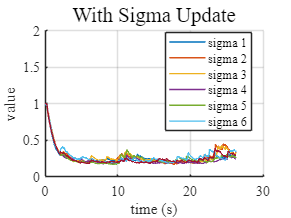


w_sim_time_sigma = w_sigma(1,:);
w_sigma_value    = w_sigma(2:end,:);

figure;
hold on
plot(w_sim_time_sigma, w_sigma_value);
hold off
title("With Sigma Update")
xlabel("time (s)")
ylabel("value")
ylim([0 2])
legend("sigma 1", "sigma 2", "sigma 3", "sigma 4", "sigma 5", "sigma 6", "Location","best")

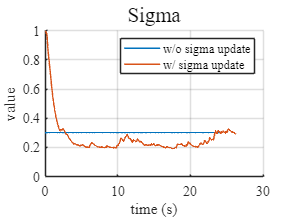


% comparision
mean_wo_sigma_value = mean(wo_sigma_value, 1);
mean_w_sigma_value = mean(w_sigma_value, 1);

figure;
hold on
plot(wo_sim_time_sigma, mean_wo_sigma_value);
plot(w_sim_time_sigma, mean_w_sigma_value);
hold off
title("Sigma")
xlabel("time (s)")
ylabel("value")
legend('w/o sigma update', 'w/ sigma update')